clear
clc
%%%%%% NEED TO KNOW BEFORE RUNNING
% h in feet, T in °C, others in SI units

% G indicates no payload, M indicates max payload, V_forward indicates forward flight speed of aircraft in m/s

% output = PowerClac(Weight,h,T,alp ,V_forward,input)
% output = [Pi;Po;Pp;Paux;PPP;lambdai];
% input(19) = 1;------means ISA +20°C condition
% input(19) = 0;------means normal condition

% for ISA +20°C condition 
% pressure assumed to be unchanged, rho changes with temperature change


% alp angle is define as a vector instead of a number, same length as the V_forward


%%% Assumption
% T_upper = T_lower = W/2
% turboshaft engine

% COMMON Defined:
% V_forward, mu, V_tip, V_cruise
% h_cruise, hh-----[h_1,h_2,h_cruise,h_3,h_4]
% GTOW, MTOW
% kappa_: i,02,04,int,trans
% sigema is not equal to solidity

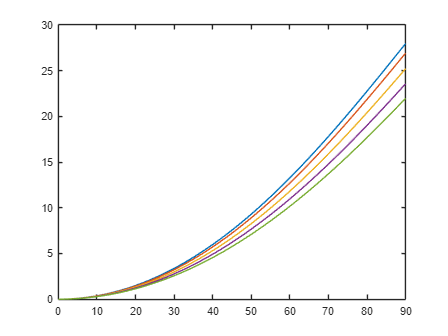

%%%%%% COMMON VALUES
%%% Environment
rho_0 = 1.225;                   % kg/m^3
T_0 = 288.2;                     % K
P_0 = 101325;                    % pa
gamma = 1.4;
R_0 = 287.05;
g = 9.8067;                      % m/s^2
T_trans = 272.15;                         % K to °C

%%% Aero team
MTOW = 3964.054;                     % kg     % max take off weight
Wpay = 800;                      % kg     % Weight of the payload
Nb = 3;
R = 5.3;                         % m
c = 0.2650;                       % m      % chord length
Cd0 = 0.01;
omega = 41.5153;                          % rotational speed
f = 3.4177;                               % equivalent wetted area
t_c = 0.08;                               % thickness ratio
M_dd = 0.86;                              % drag divergence Mach number
sweep = 30;                      % degree % sweep angle
kappa_ii = 1.1;                        % induce factor
kappa_02 = 4;                             % profile factor (mu^2 term)
kappa_04 = 5/8;                           % profile factor (mu^4 term)
kappa_int = 1.219;                        % interference factor
T_max = 40000;                   % N      % max thrust 
Cl_alpha = 5.7;                   % per rad
twist_upper = -11;
twist_lower = -6;
picth_upper = 11.61;
pitch_lower = 7.82;
picth_upper_hover = 15.98;
pitch_lower_hover = 13.3;
CT_upper = 0.003798;
CT_lower = 0.003022;
e = 0.08;

%%% syst team
Ne = 2;                                   % number of engines
Paux_total = 4*10^3;                      % power needed (the on board equipments)
SFC = 8.8611*10^-8;                 % kg/(W*s)
Wf = 1000.674;                                 % initial fuel weight
Ptotal = 1335*10^3;                    % total power provided by engines
kappa_trans = 1/0.9222;                        % transmission factor
% kappa_EngineInstallationLosses = 0.98;                        % Engine Installation Losses

%%%%%% Initial calc
GTOW = (MTOW - Wpay) * g;         % N    % gross take off weight(no payload)
MTOW = MTOW * g;                  % N
Wpay = Wpay * g;                  % N
Wf = Wf * g;                      % N
A = pi * R^2;                     % m^2  % rotor area
solidity = Nb * c / (pi * R);              % solidity
T_0 = T_0 - T_trans;              % °C
V_cruise = 66.8778;               % m/s
V_forward = 0:0.1:90;
mu = V_forward ./ (omega * R);
V_tip = omega*R;


h_cruise = 5000;
hh = [1000,2500,h_cruise,7500,10000];

%%% alp estimate
alp_msl_G = atan(((0.5*rho_0*f).* V_forward.^2) ./ GTOW);     % in rad
alp_msl_M = atan(((0.5*rho_0*f).* V_forward.^2) ./ MTOW);
alp_G = zeros(5,length(V_forward));
alp_M = zeros(5,length(V_forward));
for i = 1:length(hh)
    alp_G(i,:) = atan(((0.5*rho_0*(1-6.876*10^-6*hh(i))^4.265*f).* V_forward.^2) ./ GTOW);
    alp_M(i,:) = atan(((0.5*rho_0*(1-6.876*10^-6*hh(i))^4.265*f).* V_forward.^2) ./ MTOW);
end
plot(V_forward,rad2deg(alp_G))

input = zeros(1,31);
input(1) = omega;
input(2) = R;
input(3) = A;
input(4) = rho_0;
input(5) = kappa_ii;
input(6) = kappa_int;
input(7) = f;
input(8) = Paux_total;
input(9) = solidity;
input(10) = Cd0;
input(11) = kappa_02;
input(12) = kappa_04;
input(13) = gamma;
input(14) = R_0;
input(15) = t_c;
input(16) = sweep;
input(17) = M_dd;
input(18) = kappa_trans;
input(19) = 0;                   %ISA factor
input(20) = T_trans;
input(21) = Cl_alpha;
input(22) = twist_upper;
input(23) = twist_lower;
input(24) = picth_upper;
input(25) = pitch_lower;
input(26) = picth_upper_hover;
input(27) = pitch_lower_hover;
input(28) = CT_upper;
input(29) = CT_lower;
input(30) = h_cruise;
input(31) = e;


%%% power clac
%%% assumption: forward flight-collective pitch equal to cruise collective
%%% pitch, alp for upper rotor and lower rotor are the same
TT = (15-0.001981.*hh) + T_trans;
T_cruise = TT(3);
PPP_1_G = PowerClac(GTOW,hh(1),TT(1) ,V_forward,input);
PPP_2_G = PowerClac(GTOW,hh(2),TT(2) ,V_forward,input);
PPP_3_G = PowerClac(GTOW,hh(3),TT(3) ,V_forward,input);
PPP_4_G = PowerClac(GTOW,hh(4),TT(4) ,V_forward,input);
PPP_5_G = PowerClac(GTOW,hh(5),TT(5) ,V_forward,input);
P_1_G = PPP_1_G(5,:);
P_2_G = PPP_2_G(5,:);
P_3_G = PPP_3_G(5,:);
P_4_G = PPP_4_G(5,:);
P_5_G = PPP_5_G(5,:);
PPP_1_M = PowerClac(MTOW,hh(1),TT(1) ,V_forward,input);
PPP_2_M = PowerClac(MTOW,hh(2),TT(2) ,V_forward,input);
PPP_3_M = PowerClac(MTOW,hh(3),TT(3) ,V_forward,input);
PPP_4_M = PowerClac(MTOW,hh(4),TT(4) ,V_forward,input);
PPP_5_M = PowerClac(MTOW,hh(5),TT(5) ,V_forward,input);
P_1_M = PPP_1_M(5,:);
P_2_M = PPP_2_M(5,:);
P_3_M = PPP_3_M(5,:);
P_4_M = PPP_4_M(5,:);
P_5_M = PPP_5_M(5,:);
input(19) = 1;
PPP_1_G_20 = PowerClac(GTOW,hh(1),TT(1) ,V_forward,input);
PPP_2_G_20 = PowerClac(GTOW,hh(2),TT(2) ,V_forward,input);
PPP_3_G_20 = PowerClac(GTOW,hh(3),TT(3) ,V_forward,input);
PPP_4_G_20 = PowerClac(GTOW,hh(4),TT(4) ,V_forward,input);
PPP_5_G_20 = PowerClac(GTOW,hh(5),TT(5) ,V_forward,input);
P_1_G_20 = PPP_1_G_20(5,:);
P_2_G_20 = PPP_2_G_20(5,:);
P_3_G_20 = PPP_3_G_20(5,:);
P_4_G_20 = PPP_4_G_20(5,:);
P_5_G_20 = PPP_5_G_20(5,:);
PPP_1_M_20 = PowerClac(MTOW,hh(1),TT(1) ,V_forward,input);
PPP_2_M_20 = PowerClac(MTOW,hh(2),TT(2) ,V_forward,input);
PPP_3_M_20 = PowerClac(MTOW,hh(3),TT(3) ,V_forward,input);
PPP_4_M_20 = PowerClac(MTOW,hh(4),TT(4) ,V_forward,input);
PPP_5_M_20 = PowerClac(MTOW,hh(5),TT(5) ,V_forward,input);
P_1_M_20 = PPP_1_M_20(5,:);
P_2_M_20 = PPP_2_M_20(5,:);
P_3_M_20 = PPP_3_M_20(5,:);
P_4_M_20 = PPP_4_M_20(5,:);
P_5_M_20 = PPP_5_M_20(5,:);
input(19) = 0;  

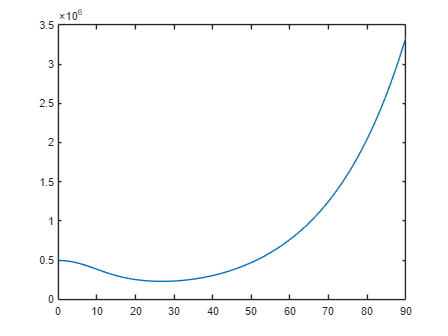

%%%%%% Power estimation (msl)
h_msl = 0;
T_msl = ((15 - 0.001981 * h_msl) + T_trans);
PPP_msl_G = PowerClac(GTOW,h_msl,T_msl ,V_forward,input);
PPP_msl_M = PowerClac(MTOW,h_msl,T_msl ,V_forward,input);

P_msl_G = PPP_msl_G(5,:);
Pi_msl_G = PPP_msl_G(1,:);

P_msl_M = PPP_msl_M(5,:);
Pi_msl_M = PPP_msl_M(1,:);

Po_msl = PPP_msl_G(2,:);
Pp_msl = PPP_msl_G(3,:);
Paux_msl = PPP_msl_G(4,:);

figure
plot(V_forward,Pi_msl_M)

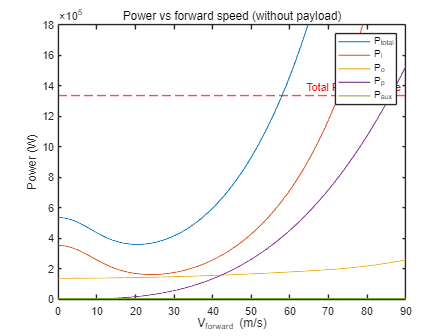


figure
plot(V_forward,P_msl_G,LineWidth=1)
hold on
plot(V_forward,Pi_msl_G,LineWidth=1)
hold on
plot(V_forward,Po_msl,LineWidth=1)
hold on
plot(V_forward,Pp_msl,LineWidth=1)
hold on
plot(V_forward,Paux_msl,LineWidth=1)
hold on
yline(Ptotal, '--r', 'Total Power avalible');
hold on
legend('P_t_o_t_a_l','P_i','P_o','P_p','P_a_u_x')
title('Power vs forward speed (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
ylim([0 1.8*10^6])
hold off

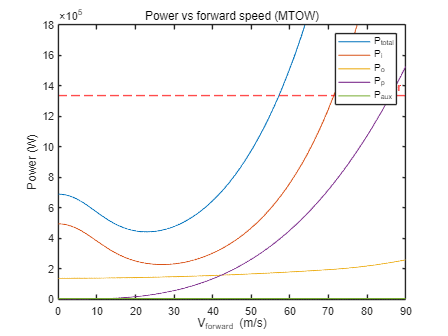

figure
plot(V_forward,P_msl_M,LineWidth=1)
hold on
plot(V_forward,Pi_msl_M,LineWidth=1)
hold on
plot(V_forward,Po_msl,LineWidth=1)
hold on
plot(V_forward,Pp_msl,LineWidth=1)
hold on
plot(V_forward,Paux_msl,LineWidth=1)
hold on
yline(Ptotal, '--r', 'Total Power');
hold on
legend('P_t_o_t_a_l','P_i','P_o','P_p','P_a_u_x')
title('Power vs forward speed (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
ylim([0 1.8*10^6])
hold off

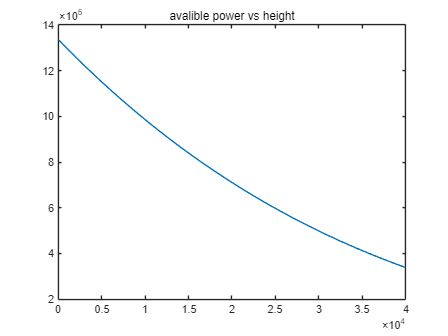

%%%%%% Ceiling for GTOW&MTOW
h_ceil = 0:100:40000;
P_ceiling_G = zeros(length(h_ceil),length(V_forward));
P_ceiling_M = zeros(length(h_ceil),length(V_forward));
P_availible = zeros(length(h_ceil),length(V_forward));
P_intersect_G = zeros(1,length(V_forward));
h_intersect_G = zeros(1,length(V_forward));
P_intersect_M = zeros(1,length(V_forward));
h_intersect_M = zeros(1,length(V_forward));
V_intersect_G = V_forward;
V_intersect_M = V_forward;

%%% Power clac
for ii = 1:length(h_ceil)
    h_ceil_i = h_ceil(ii);
    T_ceil = ((15 - 0.001981 * h_ceil_i) + T_trans);

    PPP_ceil_G = PowerClac(GTOW,h_ceil_i,T_ceil ,V_forward,input);
    PPP_ceil_M = PowerClac(MTOW,h_ceil_i,T_ceil ,V_forward,input);
    P_ceiling_G(ii,:) = 0.3 * GTOW * kappa_trans + PPP_ceil_G(5,:);
    P_ceiling_M(ii,:) = 0.3 * MTOW * kappa_trans + PPP_ceil_M(5,:);
end

%%% Availible power calc
P_ratio = (1 - 6.876*10^-6 .* h_ceil).^5.265;
rho_ratio = (1 - 6.876 * 10^-6 .* h_ceil).^4.265;
T_ratio = P_ratio./rho_ratio;
P_avalible = Ptotal.*P_ratio./T_ratio;
figure
plot(h_ceil,P_avalible);
title('avalible power vs height')

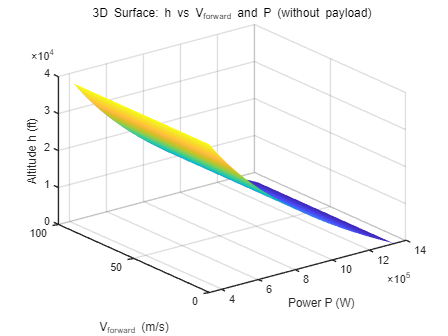

for jj = 1:length(V_forward)
    P_availible(:,jj) = P_avalible';
end
[VV, HH] = meshgrid(V_forward, h_ceil);
figure
surf(P_availible, VV, HH);
xlabel('Power P (W)');
ylabel('V_f_o_r_w_a_r_d (m/s)');
zlabel('Altitude h (ft)');
title('3D Surface: h vs V_f_o_r_w_a_r_d and P (without payload)');
grid on
shading interp
hold off

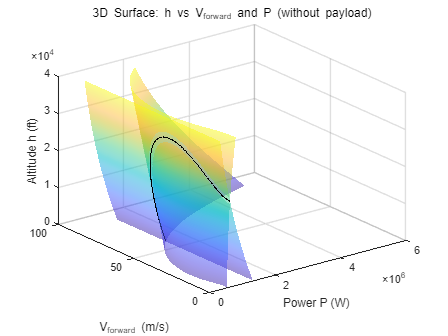


%%% intersection
for iii = 1:length(V_forward)
    PP_ceiling_G = P_ceiling_G(:,iii)';
    PP_ceiling_M = P_ceiling_M(:,iii)';
    PP_availible = P_availible(:,iii)';
    [~,ceil_idx_G] = min(abs(PP_ceiling_G - PP_availible));
    [~,ceil_idx_M] = min(abs(PP_ceiling_M - PP_availible));
    h_intersect_G(iii) = h_ceil(ceil_idx_G);
    P_intersect_G(iii) = P_ceiling_G(ceil_idx_G,iii);
    h_intersect_M(iii) = h_ceil(ceil_idx_M);
    P_intersect_M(iii) = P_ceiling_M(ceil_idx_M,iii);
    if h_intersect_G(iii) == 0
        P_intersect_G(iii+1:end) = P_intersect_G(iii);
        V_intersect_G(iii+1:end) = V_intersect_G(iii);
        P_intersect_M(iii+1:end) = P_intersect_M(iii);
        V_intersect_M(iii+1:end) = V_intersect_M(iii);
        break
    end
end

%%% plots
figure
s1 = surf(P_ceiling_G, VV, HH, HH);
s1.FaceAlpha = 0.5;
hold on
s2 = surf(P_availible, VV, HH);
s2.FaceAlpha = 0.5; 
hold on
plot3(P_intersect_G,V_intersect_G,h_intersect_G,"Color",'k','LineWidth',1)
xlabel('Power P (W)');
ylabel('V_f_o_r_w_a_r_d (m/s)');
zlabel('Altitude h (ft)');
title('3D Surface: h vs V_f_o_r_w_a_r_d and P (without payload)');
grid on
shading interp
hold off

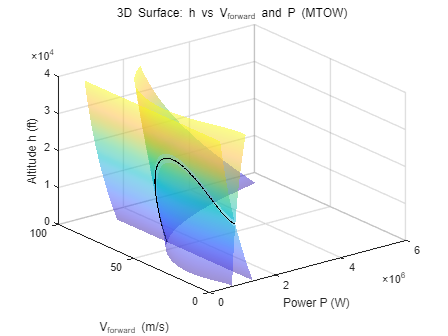

figure
s1 = surf(P_ceiling_M, VV, HH, HH);
s1.FaceAlpha = 0.5;
hold on
s2 = surf(P_availible, VV, HH);
s2.FaceAlpha = 0.5; 
hold on
plot3(P_intersect_M,V_intersect_M,h_intersect_M,"Color",'k','LineWidth',1)
xlabel('Power P (W)');
ylabel('V_f_o_r_w_a_r_d (m/s)');
zlabel('Altitude h (ft)');
title('3D Surface: h vs V_f_o_r_w_a_r_d and P (MTOW)');
grid on
shading interp
hold off

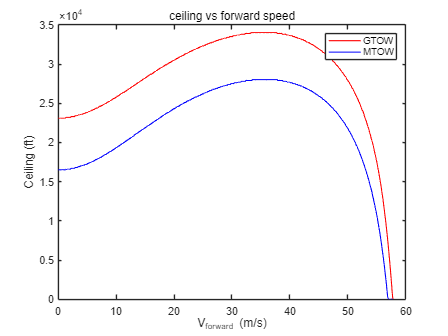

figure
plot(V_intersect_G,h_intersect_G,"Color",'r','LineWidth',1)
hold on
plot(V_intersect_M,h_intersect_M,"Color",'b','LineWidth',1)
legend('GTOW','MTOW')
title('ceiling vs forward speed')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Ceiling (ft)')

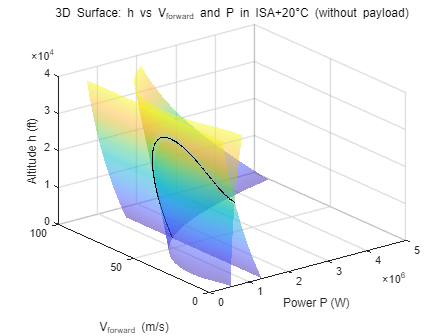

%%%%%% Max ceiling for ISA+20°C Temperature condition (GTOW&MTOW)
P_ceiling_G_amb = zeros(length(h_ceil),length(V_forward));
P_ceiling_M_amb = zeros(length(h_ceil),length(V_forward));
P_availible_amb = zeros(length(h_ceil),length(V_forward));
P_intersect_G_amb = zeros(1,length(V_forward));
h_intersect_G_amb = zeros(1,length(V_forward));
P_intersect_M_amb = zeros(1,length(V_forward));
h_intersect_M_amb = zeros(1,length(V_forward));
V_intersect_G_amb = V_forward;
V_intersect_M_amb = V_forward;
input(19) = 1;

%%% Power clac
for ii = 1:length(h_ceil)
    h_ceil_i = h_ceil(ii);
    T_ceil_amb = ((35 - 0.001981 * h_ceil_i) + T_trans);

    PPP_ceil_G_amb = PowerClac(GTOW,h_ceil_i,T_ceil_amb ,V_forward,input);
    PPP_ceil_M_amb = PowerClac(MTOW,h_ceil_i,T_ceil_amb ,V_forward,input);
    P_ceiling_G_amb(ii,:) = 0.3 * GTOW * kappa_trans + PPP_ceil_G_amb(5,:);
    P_ceiling_M_amb(ii,:) = 0.3 * MTOW * kappa_trans + PPP_ceil_M_amb(5,:);
end
input(19) = 0;

%%% intersection
for iii = 1:length(V_forward)
    PP_ceiling_G_amb = P_ceiling_G_amb(:,iii)';
    PP_ceiling_M_amb = P_ceiling_M_amb(:,iii)';
    PP_availible_amb = P_availible(:,iii)';
    [~,ceil_idx_G_amb] = min(abs(PP_ceiling_G_amb - PP_availible));
    [~,ceil_idx_M_amb] = min(abs(PP_ceiling_M_amb - PP_availible));
    h_intersect_G_amb(iii) = h_ceil(ceil_idx_G_amb);
    P_intersect_G_amb(iii) = P_ceiling_G_amb(ceil_idx_G_amb,iii);
    h_intersect_M_amb(iii) = h_ceil(ceil_idx_M_amb);
    P_intersect_M_amb(iii) = P_ceiling_M_amb(ceil_idx_M_amb,iii);
    if h_intersect_G_amb(iii) == 0
        P_intersect_G_amb(iii+1:end) = P_intersect_G_amb(iii);
        V_intersect_G_amb(iii+1:end) = V_intersect_G_amb(iii);
        P_intersect_M_amb(iii+1:end) = P_intersect_M_amb(iii);
        V_intersect_M_amb(iii+1:end) = V_intersect_M_amb(iii);
        break
    end
end

%%% plots
figure
s1 = surf(P_ceiling_G_amb, VV, HH, HH);
s1.FaceAlpha = 0.5;
hold on
s2 = surf(P_availible, VV, HH);
s2.FaceAlpha = 0.5; 
hold on
plot3(P_intersect_G_amb,V_intersect_G_amb,h_intersect_G_amb,"Color",'k','LineWidth',1)
xlabel('Power P (W)');
ylabel('V_f_o_r_w_a_r_d (m/s)');
zlabel('Altitude h (ft)');
title('3D Surface: h vs V_f_o_r_w_a_r_d and P in ISA+20°C (without payload)');
grid on
shading interp
hold off

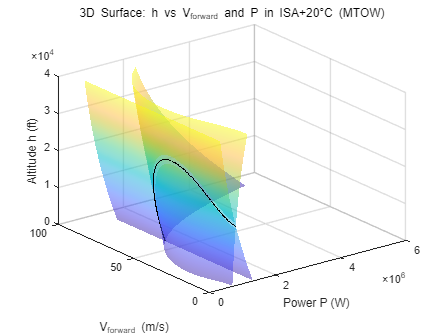

figure
s1 = surf(P_ceiling_M_amb, VV, HH, HH);
s1.FaceAlpha = 0.5;
hold on
s2 = surf(P_availible, VV, HH);
s2.FaceAlpha = 0.5; 
hold on
plot3(P_intersect_M_amb,V_intersect_M_amb,h_intersect_M_amb,"Color",'k','LineWidth',1)
xlabel('Power P (W)');
ylabel('V_f_o_r_w_a_r_d (m/s)');
zlabel('Altitude h (ft)');
title('3D Surface: h vs V_f_o_r_w_a_r_d and P in ISA+20°C (MTOW)');
grid on
shading interp
hold off

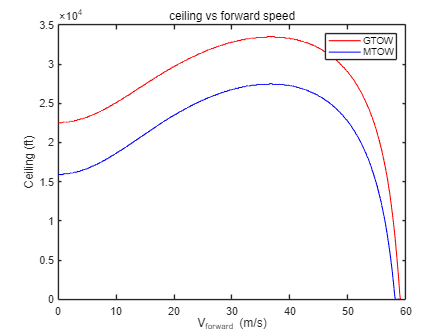

figure
plot(V_intersect_G_amb,h_intersect_G_amb,"Color",'r','LineWidth',1)
hold on
plot(V_intersect_M_amb,h_intersect_M_amb,"Color",'b','LineWidth',1)
legend('GTOW','MTOW')
title('ceiling vs forward speed')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Ceiling (ft)')

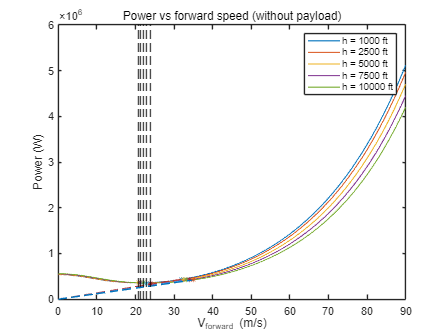

%%%%%% Max range&endurance
%%% min power---endurance
[Pmp_1, idx_1] = min(P_1_G);
[Pmp_2, idx_2] = min(P_2_G);
[Pmp_3, idx_3] = min(P_3_G);
[Pmp_4, idx_4] = min(P_4_G);
[Pmp_5, idx_5] = min(P_5_G);
Vmp_G = [V_forward(idx_1),V_forward(idx_2),V_forward(idx_3),V_forward(idx_4),V_forward(idx_5)];
Pmp_G = [Pmp_1,Pmp_2,Pmp_3,Pmp_4,Pmp_5];
endurance_G = (Wf./g) ./ (SFC .* Pmp_G);

%%% min gradient---range
k_1 = P_1_G ./ V_forward;
k_2 = P_2_G ./ V_forward;
k_3 = P_3_G ./ V_forward;
k_4 = P_4_G ./ V_forward;
k_5 = P_5_G ./ V_forward;
[~, idx_range_1] = min(k_1);
[~, idx_range_2] = min(k_2);
[~, idx_range_3] = min(k_3);
[~, idx_range_4] = min(k_4);
[~, idx_range_5] = min(k_5);
Vrange_G = [V_forward(idx_range_1),V_forward(idx_range_2),V_forward(idx_range_3),V_forward(idx_range_4),V_forward(idx_range_5)];
Prange_G = [P_1_G(idx_range_1),P_2_G(idx_range_2),P_3_G(idx_range_3),P_4_G(idx_range_4),P_5_G(idx_range_5)];
range_G = (Vrange_G .* (Wf./g)) ./ (SFC .* Prange_G);

%%% plots
figure
plot(V_forward,P_1_G,LineWidth=1)
hold on
plot(V_forward,P_2_G,LineWidth=1)
hold on
plot(V_forward,P_3_G,LineWidth=1)
hold on
plot(V_forward,P_4_G,LineWidth=1)
hold on
plot(V_forward,P_5_G,LineWidth=1)
hold on
plot(Vmp_G,Pmp_G)
hold on
plot([0,V_forward(idx_range_1)], [0,P_1_G(idx_range_1)],'--');
hold on
plot(V_forward(idx_range_1), P_1_G(idx_range_1), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_2)], [0,P_2_G(idx_range_2)],'--');
hold on
plot(V_forward(idx_range_2), P_2_G(idx_range_2), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_3)], [0,P_3_G(idx_range_3)],'--');
hold on
plot(V_forward(idx_range_3), P_3_G(idx_range_3), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_4)], [0,P_4_G(idx_range_4)],'--');
hold on
plot(V_forward(idx_range_4), P_4_G(idx_range_4), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_5)], [0,P_5_G(idx_range_5)],'--');
hold on
plot(V_forward(idx_range_5), P_5_G(idx_range_5), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(1),'--k')
hold on
plot(Vmp_G(1), Pmp_G(1), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(2),'--k')
hold on
plot(Vmp_G(2), Pmp_G(2), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(3),'--k')
hold on
plot(Vmp_G(3), Pmp_G(3), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(4),'--k')
hold on
plot(Vmp_G(4), Pmp_G(4), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(5),'--k')
hold on
plot(Vmp_G(5), Pmp_G(5), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('Power vs forward speed (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')

hold off

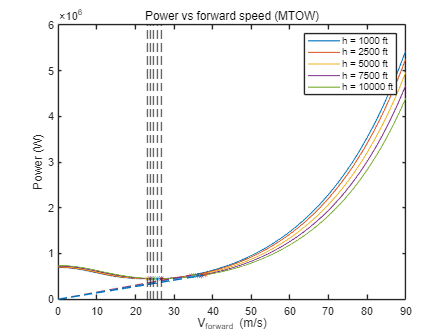

%%% min power---endurance
[Pmp_1, idx_1] = min(P_1_M);
[Pmp_2, idx_2] = min(P_2_M);
[Pmp_3, idx_3] = min(P_3_M);
[Pmp_4, idx_4] = min(P_4_M);
[Pmp_5, idx_5] = min(P_5_M);
Vmp_M = [V_forward(idx_1),V_forward(idx_2),V_forward(idx_3),V_forward(idx_4),V_forward(idx_5)];
Pmp_M = [Pmp_1,Pmp_2,Pmp_3,Pmp_4,Pmp_5];
endurance_M = (Wf./g) ./ (SFC .* Pmp_M);

%%% min gradient---range
k_1 = P_1_M ./ V_forward;
k_2 = P_2_M ./ V_forward;
k_3 = P_3_M ./ V_forward;
k_4 = P_4_M ./ V_forward;
k_5 = P_5_M ./ V_forward;
[~, idx_range_1] = min(k_1);
[~, idx_range_2] = min(k_2);
[~, idx_range_3] = min(k_3);
[~, idx_range_4] = min(k_4);
[~, idx_range_5] = min(k_5);
Vrange_M = [V_forward(idx_range_1),V_forward(idx_range_2),V_forward(idx_range_3),V_forward(idx_range_4),V_forward(idx_range_5)];
Prange_M = [P_1_M(idx_range_1),P_2_M(idx_range_2),P_3_M(idx_range_3),P_4_M(idx_range_4),P_5_M(idx_range_5)];
range_M = (Vrange_M .* (Wf./g)) ./ (SFC .* Prange_M);

%%% plots
figure
plot(V_forward,P_1_M,LineWidth=1)
hold on
plot(V_forward,P_2_M,LineWidth=1)
hold on
plot(V_forward,P_3_M,LineWidth=1)
hold on
plot(V_forward,P_4_M,LineWidth=1)
hold on
plot(V_forward,P_5_M,LineWidth=1)
hold on
plot(Vmp_M,Pmp_M)
hold on
plot([0,V_forward(idx_range_3)], [0,P_3_M(idx_range_3)],'--');
hold on
plot(V_forward(idx_range_3), P_3_M(idx_range_3), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_1)], [0,P_1_M(idx_range_1)],'--');
hold on
plot(V_forward(idx_range_1), P_1_M(idx_range_1), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_2)], [0,P_2_M(idx_range_2)],'--');
hold on
plot(V_forward(idx_range_2), P_2_M(idx_range_2), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_4)], [0,P_4_M(idx_range_4)],'--');
hold on
plot(V_forward(idx_range_4), P_4_M(idx_range_4), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_5)], [0,P_5_M(idx_range_5)],'--');
hold on
plot(V_forward(idx_range_5), P_5_M(idx_range_5), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(1),'--')
hold on
plot(Vmp_M(1), Pmp_M(1), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(2),'--')
hold on
plot(Vmp_M(2), Pmp_M(2), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(3),'--')
hold on
plot(Vmp_M(3), Pmp_M(3), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(4),'--')
hold on
plot(Vmp_M(4), Pmp_M(4), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(5),'--')
hold on
plot(Vmp_M(5), Pmp_M(5), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('Power vs forward speed (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

Trange = table(hh',Vrange_M',Prange_M'./1000,range_M'./1000,Vrange_G',Prange_G'./1000,range_G'./1000,'VariableNames', {'Height_ft', 'Vrange_M (m/s)', 'Prange_M (KW)', 'Range_MTOW (km)', 'Vrange_G (m/s)', 'Prange_G (KW)', 'Range_GTOW (km)'});
Tendurance = table(hh',Vmp_M',Pmp_M'./1000,endurance_M'./3600,Vmp_G',Pmp_G'./1000,endurance_G'./3600,'VariableNames', {'Height_ft', 'Vendur_M (m/s)', 'Pendur_M (KW)', 'Endur_MTOW (h)', 'Vendur_G (m/s)', 'Pendur_G (KW)', 'Endur_GTOW (h)'});
disp(Trange)

    Height_ft    Vrange_M (m/s)    Prange_M (KW)    Range_MTOW (km)    Vrange_G (m/s)    Prange_G (KW)    Range_GTOW (km)
    _________    ______________    _____________    _______________    ______________    _____________    _______________

       1000           34.5            528.74            736.85                32            435.02            830.71     
       2500             35            526.89            750.15              32.4            430.81            849.31     
       5000             36            526.79            771.73              33.3            427.33            880.02     
       7500             37            527.28            792.44              34.1             423.1            910.16     
      10000           38.1             529.8            812.11              35.1             421.9            939.51     



disp(Tendurance)

    Height_ft    Vendur_M (m/s)    Pendur_M (KW)    Endur_MTOW (h)    Vendur_G (m/s)    Pendur_G (KW)    Endur_GTOW (h)
    _________    ______________    _____________    ______________    ______________    _____________    ______________

       1000           23.2            441.88             7.099             20.8            358.19            8.7577    
       2500           23.8            442.11            7.0954             21.2            356.52            8.7988    
       5000           24.7            443.47            7.0735               22            354.56            8.8474    
       7500           25.6             446.1            7.0319             22.9            353.65            8.8702    
      10000           26.6            450.02            6.9707             23.8             353.8            8.8664    



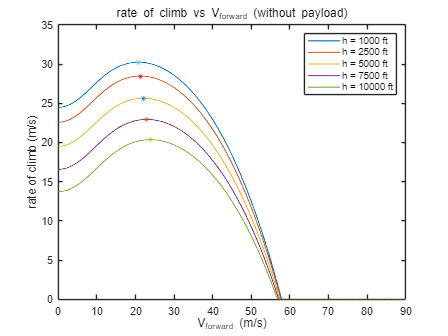

%%%%%% Climb performance (V_forward indicates climb speed, Vc indicates rate of climb)
%%% Power avalible
P_ratio = (1 - 6.876*10^-6 .* hh).^5.265;
rho_ratio = (1 - 6.876 * 10^-6 .* hh).^4.265;
T_ratio = P_ratio./rho_ratio;
P_a = Ptotal.*P_ratio./T_ratio;

%%% rate of climb clac
Vc_1_M = (P_a(1) - P_1_M) ./ MTOW;
Vc_2_M = (P_a(2) - P_2_M) ./ MTOW;
Vc_3_M = (P_a(3) - P_3_M) ./ MTOW;
Vc_4_M = (P_a(4) - P_4_M) ./ MTOW;
Vc_5_M = (P_a(5) - P_5_M) ./ MTOW;
Vc_1_G = (P_a(1) - P_1_G) ./ GTOW;
Vc_2_G = (P_a(2) - P_2_G) ./ GTOW;
Vc_3_G = (P_a(3) - P_3_G) ./ GTOW;
Vc_4_G = (P_a(4) - P_4_G) ./ GTOW;
Vc_5_G = (P_a(5) - P_5_G) ./ GTOW;
Vc_1_G(Vc_1_G < 0) = 0;
Vc_2_G(Vc_2_G < 0) = 0;
Vc_3_G(Vc_3_G < 0) = 0;
Vc_4_G(Vc_4_G < 0) = 0;
Vc_5_G(Vc_5_G < 0) = 0;
Vc_1_M(Vc_1_M < 0) = 0;
Vc_2_M(Vc_2_M < 0) = 0;
Vc_3_M(Vc_3_M < 0) = 0;
Vc_4_M(Vc_4_M < 0) = 0;
Vc_5_M(Vc_5_M < 0) = 0;

%%% max rate of climb
[~,idx_Vc_1_G] = max(Vc_1_G);
[~,idx_Vc_2_G] = max(Vc_2_G);
[~,idx_Vc_3_G] = max(Vc_3_G);
[~,idx_Vc_4_G] = max(Vc_4_G);
[~,idx_Vc_5_G] = max(Vc_5_G);
[~,idx_Vc_1_M] = max(Vc_1_M);
[~,idx_Vc_2_M] = max(Vc_2_M);
[~,idx_Vc_3_M] = max(Vc_3_M);
[~,idx_Vc_4_M] = max(Vc_4_M);
[~,idx_Vc_5_M] = max(Vc_5_M);

%%% plots
figure
plot(V_forward,Vc_1_G,LineWidth=1);
hold on
plot(V_forward,Vc_2_G,LineWidth=1);
hold on
plot(V_forward,Vc_3_G,LineWidth=1);
hold on
plot(V_forward,Vc_4_G,LineWidth=1);
hold on
plot(V_forward,Vc_5_G,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_G), Vc_1_G(idx_Vc_1_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_G), Vc_2_G(idx_Vc_2_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_G), Vc_3_G(idx_Vc_3_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_G), Vc_4_G(idx_Vc_4_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_5_G), Vc_5_G(idx_Vc_5_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('rate of climb vs V_f_o_r_w_a_r_d (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
hold off

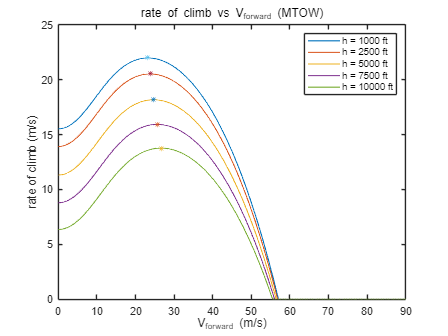

figure
plot(V_forward,Vc_1_M,LineWidth=1);
hold on
plot(V_forward,Vc_2_M,LineWidth=1);
hold on
plot(V_forward,Vc_3_M,LineWidth=1);
hold on
plot(V_forward,Vc_4_M,LineWidth=1);
hold on
plot(V_forward,Vc_5_M,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_M), Vc_1_M(idx_Vc_1_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_M), Vc_2_M(idx_Vc_2_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_M), Vc_3_M(idx_Vc_3_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_M), Vc_4_M(idx_Vc_4_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_5_M), Vc_5_M(idx_Vc_5_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('rate of climb vs V_f_o_r_w_a_r_d (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
hold off

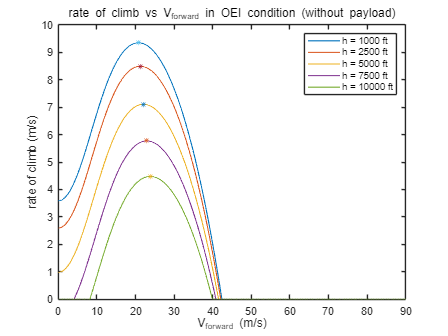

%%%%%% Climb performance OEI
%%% rate of climb clac
Vc_1_M_OEI = (P_a(1)/2 - P_1_M) ./ MTOW;
Vc_2_M_OEI = (P_a(2)/2 - P_2_M) ./ MTOW;
Vc_3_M_OEI = (P_a(3)/2 - P_3_M) ./ MTOW;
Vc_4_M_OEI = (P_a(4)/2 - P_4_M) ./ MTOW;
Vc_5_M_OEI = (P_a(5)/2 - P_5_M) ./ MTOW;
Vc_1_G_OEI = (P_a(1)/2 - P_1_G) ./ GTOW;
Vc_2_G_OEI = (P_a(2)/2 - P_2_G) ./ GTOW;
Vc_3_G_OEI = (P_a(3)/2 - P_3_G) ./ GTOW;
Vc_4_G_OEI = (P_a(4)/2 - P_4_G) ./ GTOW;
Vc_5_G_OEI = (P_a(5)/2 - P_5_G) ./ GTOW;
Vc_1_G_OEI(Vc_1_G_OEI < 0) = 0;
Vc_2_G_OEI(Vc_2_G_OEI < 0) = 0;
Vc_3_G_OEI(Vc_3_G_OEI < 0) = 0;
Vc_4_G_OEI(Vc_4_G_OEI < 0) = 0;
Vc_5_G_OEI(Vc_5_G_OEI < 0) = 0;
Vc_1_M_OEI(Vc_1_M_OEI < 0) = 0;
Vc_2_M_OEI(Vc_2_M_OEI < 0) = 0;
Vc_3_M_OEI(Vc_3_M_OEI < 0) = 0;
Vc_4_M_OEI(Vc_4_M_OEI < 0) = 0;
Vc_5_M_OEI(Vc_5_M_OEI < 0) = 0;

%%% max rate of climb
[~,idx_Vc_1_G_OEI] = max(Vc_1_G_OEI);
[~,idx_Vc_2_G_OEI] = max(Vc_2_G_OEI);
[~,idx_Vc_3_G_OEI] = max(Vc_3_G_OEI);
[~,idx_Vc_4_G_OEI] = max(Vc_4_G_OEI);
[~,idx_Vc_5_G_OEI] = max(Vc_5_G_OEI);
[~,idx_Vc_1_M_OEI] = max(Vc_1_M_OEI);
[~,idx_Vc_2_M_OEI] = max(Vc_2_M_OEI);
[~,idx_Vc_3_M_OEI] = max(Vc_3_M_OEI);
[~,idx_Vc_4_M_OEI] = max(Vc_4_M_OEI);
[~,idx_Vc_5_M_OEI] = max(Vc_5_M_OEI);

%%% plots
figure
plot(V_forward,Vc_1_G_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_2_G_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_3_G_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_4_G_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_5_G_OEI,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_G_OEI), Vc_1_G_OEI(idx_Vc_1_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_G_OEI), Vc_2_G_OEI(idx_Vc_2_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_G_OEI), Vc_3_G_OEI(idx_Vc_3_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_G_OEI), Vc_4_G_OEI(idx_Vc_4_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_5_G_OEI), Vc_5_G_OEI(idx_Vc_5_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('rate of climb vs V_f_o_r_w_a_r_d in OEI condition (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
hold off

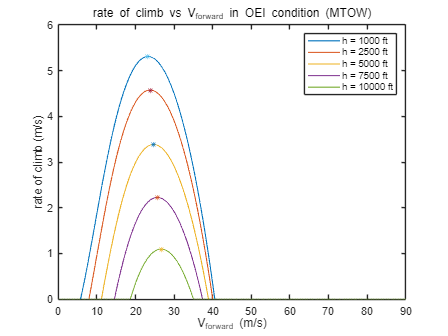

figure
plot(V_forward,Vc_1_M_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_2_M_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_3_M_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_4_M_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_5_M_OEI,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_M_OEI), Vc_1_M_OEI(idx_Vc_1_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_M_OEI), Vc_2_M_OEI(idx_Vc_2_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_M_OEI), Vc_3_M_OEI(idx_Vc_3_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_M_OEI), Vc_4_M_OEI(idx_Vc_4_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_5_M_OEI), Vc_5_M_OEI(idx_Vc_5_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('rate of climb vs V_f_o_r_w_a_r_d in OEI condition (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
hold off

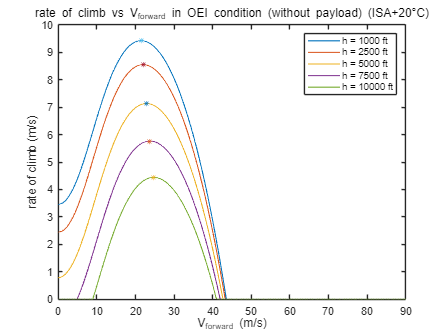

%%%%%% Climb performance OEI in ISA+20°C condition
%%% rate of climb clac
Vc_1_M_OEI_20 = (P_a(1)/2 - P_1_M_20) ./ MTOW;
Vc_2_M_OEI_20 = (P_a(2)/2 - P_2_M_20) ./ MTOW;
Vc_3_M_OEI_20 = (P_a(3)/2 - P_3_M_20) ./ MTOW;
Vc_4_M_OEI_20 = (P_a(4)/2 - P_4_M_20) ./ MTOW;
Vc_5_M_OEI_20 = (P_a(5)/2 - P_5_M_20) ./ MTOW;
Vc_1_G_OEI_20 = (P_a(1)/2 - P_1_G_20) ./ GTOW;
Vc_2_G_OEI_20 = (P_a(2)/2 - P_2_G_20) ./ GTOW;
Vc_3_G_OEI_20 = (P_a(3)/2 - P_3_G_20) ./ GTOW;
Vc_4_G_OEI_20 = (P_a(4)/2 - P_4_G_20) ./ GTOW;
Vc_5_G_OEI_20 = (P_a(5)/2 - P_5_G_20) ./ GTOW;
Vc_1_G_OEI_20(Vc_1_G_OEI_20 < 0) = 0;
Vc_2_G_OEI_20(Vc_2_G_OEI_20 < 0) = 0;
Vc_3_G_OEI_20(Vc_3_G_OEI_20 < 0) = 0;
Vc_4_G_OEI_20(Vc_4_G_OEI_20 < 0) = 0;
Vc_5_G_OEI_20(Vc_5_G_OEI_20 < 0) = 0;
Vc_1_M_OEI_20(Vc_1_M_OEI_20 < 0) = 0;
Vc_2_M_OEI_20(Vc_2_M_OEI_20 < 0) = 0;
Vc_3_M_OEI_20(Vc_3_M_OEI_20 < 0) = 0;
Vc_4_M_OEI_20(Vc_4_M_OEI_20 < 0) = 0;
Vc_5_M_OEI_20(Vc_5_M_OEI_20 < 0) = 0;
input(19) = 0;

%%% max rate of climb
[~,idx_Vc_1_G_OEI] = max(Vc_1_G_OEI_20);
[~,idx_Vc_2_G_OEI] = max(Vc_2_G_OEI_20);
[~,idx_Vc_3_G_OEI] = max(Vc_3_G_OEI_20);
[~,idx_Vc_4_G_OEI] = max(Vc_4_G_OEI_20);
[~,idx_Vc_5_G_OEI] = max(Vc_5_G_OEI_20);
[~,idx_Vc_1_M_OEI] = max(Vc_1_M_OEI_20);
[~,idx_Vc_2_M_OEI] = max(Vc_2_M_OEI_20);
[~,idx_Vc_3_M_OEI] = max(Vc_3_M_OEI_20);
[~,idx_Vc_4_M_OEI] = max(Vc_4_M_OEI_20);
[~,idx_Vc_5_M_OEI] = max(Vc_5_M_OEI_20);

%%% plots
figure
plot(V_forward,Vc_1_G_OEI_20,LineWidth=1);
hold on
plot(V_forward,Vc_2_G_OEI_20,LineWidth=1);
hold on
plot(V_forward,Vc_3_G_OEI_20,LineWidth=1);
hold on
plot(V_forward,Vc_4_G_OEI_20,LineWidth=1);
hold on
plot(V_forward,Vc_5_G_OEI_20,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_G_OEI), Vc_1_G_OEI_20(idx_Vc_1_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_G_OEI), Vc_2_G_OEI_20(idx_Vc_2_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_G_OEI), Vc_3_G_OEI_20(idx_Vc_3_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_G_OEI), Vc_4_G_OEI_20(idx_Vc_4_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_5_G_OEI), Vc_5_G_OEI_20(idx_Vc_5_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('rate of climb vs V_f_o_r_w_a_r_d in OEI condition (without payload) (ISA+20°C)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
hold off

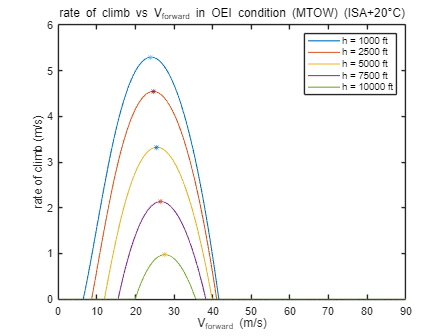

figure
plot(V_forward,Vc_1_M_OEI_20,LineWidth=1);
hold on
plot(V_forward,Vc_2_M_OEI_20,LineWidth=1);
hold on
plot(V_forward,Vc_3_M_OEI_20,LineWidth=1);
hold on
plot(V_forward,Vc_4_M_OEI_20,LineWidth=1);
hold on
plot(V_forward,Vc_5_M_OEI_20,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_M_OEI), Vc_1_M_OEI_20(idx_Vc_1_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_M_OEI), Vc_2_M_OEI_20(idx_Vc_2_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_M_OEI), Vc_3_M_OEI_20(idx_Vc_3_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_M_OEI), Vc_4_M_OEI_20(idx_Vc_4_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_5_M_OEI), Vc_5_M_OEI_20(idx_Vc_5_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('rate of climb vs V_f_o_r_w_a_r_d in OEI condition (MTOW) (ISA+20°C)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
hold off

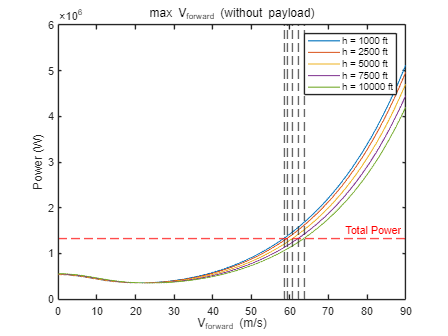

%%%%%% max forward speed
%%% Power = power availible------max forward speed
[~,idx_Vmax_1_G] = min(abs(P_1_G - Ptotal));
[~,idx_Vmax_2_G] = min(abs(P_2_G - Ptotal));
[~,idx_Vmax_3_G] = min(abs(P_3_G - Ptotal));
[~,idx_Vmax_4_G] = min(abs(P_4_G - Ptotal));
[~,idx_Vmax_5_G] = min(abs(P_5_G - Ptotal));
[~,idx_Vmax_1_M] = min(abs(P_1_M - Ptotal));
[~,idx_Vmax_2_M] = min(abs(P_2_M - Ptotal));
[~,idx_Vmax_3_M] = min(abs(P_3_M - Ptotal));
[~,idx_Vmax_4_M] = min(abs(P_4_M - Ptotal));
[~,idx_Vmax_5_M] = min(abs(P_5_M - Ptotal));

%%% plots
figure
plot(V_forward,P_1_G,LineWidth=1)
hold on
plot(V_forward,P_2_G,LineWidth=1)
hold on
plot(V_forward,P_3_G,LineWidth=1)
hold on
plot(V_forward,P_4_G,LineWidth=1)
hold on
plot(V_forward,P_5_G,LineWidth=1)
hold on
yline(Ptotal, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_G),'--')
hold on
xline(V_forward(idx_Vmax_2_G),'--')
hold on
xline(V_forward(idx_Vmax_4_G),'--')
hold on
xline(V_forward(idx_Vmax_5_G),'--')
hold on
xline(V_forward(idx_Vmax_3_G),'--')
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('max V_f_o_r_w_a_r_d (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

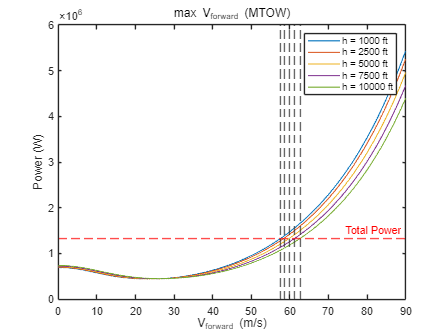

figure
plot(V_forward,P_1_M,LineWidth=1)
hold on
plot(V_forward,P_2_M,LineWidth=1)
hold on
plot(V_forward,P_3_M,LineWidth=1)
hold on
plot(V_forward,P_4_M,LineWidth=1)
hold on
plot(V_forward,P_5_M,LineWidth=1)
hold on
yline(Ptotal, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_M),'--')
hold on
xline(V_forward(idx_Vmax_2_M),'--')
hold on
xline(V_forward(idx_Vmax_4_M),'--')
hold on
xline(V_forward(idx_Vmax_5_M),'--')
hold on
xline(V_forward(idx_Vmax_3_M),'--')
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('max V_f_o_r_w_a_r_d (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

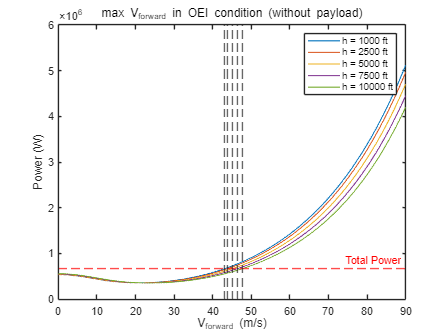

%%%%%% max forward speed (OEI)
%%% Power = power availible------max forward speed
Ptotal_OEI = Ptotal/2;
[~,idx_Vmax_1_G] = min(abs(P_1_G - Ptotal_OEI));
[~,idx_Vmax_2_G] = min(abs(P_2_G - Ptotal_OEI));
[~,idx_Vmax_3_G] = min(abs(P_3_G - Ptotal_OEI));
[~,idx_Vmax_4_G] = min(abs(P_4_G - Ptotal_OEI));
[~,idx_Vmax_5_G] = min(abs(P_5_G - Ptotal_OEI));
[~,idx_Vmax_1_M] = min(abs(P_1_M - Ptotal_OEI));
[~,idx_Vmax_2_M] = min(abs(P_2_M - Ptotal_OEI));
[~,idx_Vmax_3_M] = min(abs(P_3_M - Ptotal_OEI));
[~,idx_Vmax_4_M] = min(abs(P_4_M - Ptotal_OEI));
[~,idx_Vmax_5_M] = min(abs(P_5_M - Ptotal_OEI));

%%% plots
figure
plot(V_forward,P_1_G,LineWidth=1)
hold on
plot(V_forward,P_2_G,LineWidth=1)
hold on
plot(V_forward,P_3_G,LineWidth=1)
hold on
plot(V_forward,P_4_G,LineWidth=1)
hold on
plot(V_forward,P_5_G,LineWidth=1)
hold on
yline(Ptotal_OEI, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_G),'--')
hold on
xline(V_forward(idx_Vmax_2_G),'--')
hold on
xline(V_forward(idx_Vmax_4_G),'--')
hold on
xline(V_forward(idx_Vmax_5_G),'--')
hold on
xline(V_forward(idx_Vmax_3_G),'--')
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('max V_f_o_r_w_a_r_d in OEI condition (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

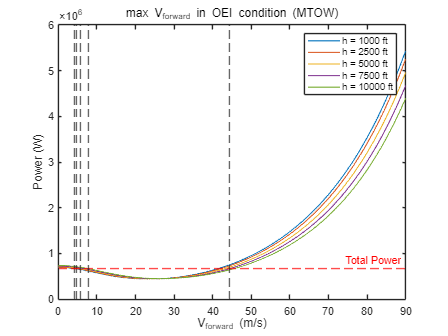

figure
plot(V_forward,P_1_M,LineWidth=1)
hold on
plot(V_forward,P_2_M,LineWidth=1)
hold on
plot(V_forward,P_3_M,LineWidth=1)
hold on
plot(V_forward,P_4_M,LineWidth=1)
hold on
plot(V_forward,P_5_M,LineWidth=1)
hold on
xline(V_forward(idx_Vmax_1_M),'--')
hold on
xline(V_forward(idx_Vmax_2_M),'--')
hold on
yline(Ptotal_OEI, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_4_M),'--')
hold on
xline(V_forward(idx_Vmax_5_M),'--')
hold on
xline(V_forward(idx_Vmax_3_M),'--')
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('max V_f_o_r_w_a_r_d in OEI condition (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

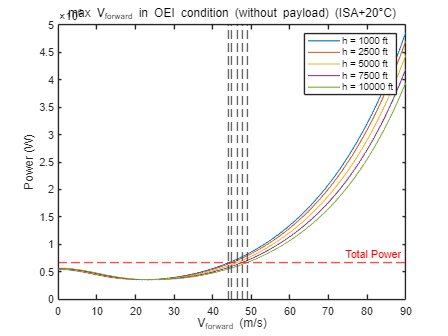

%%%%%% max forward speed (OEI)  (ISA+20°C)
%%% Power = power availible------max forward speed
Ptotal_OEI = Ptotal/2;
[~,idx_Vmax_1_G] = min(abs(P_1_G_20 - Ptotal_OEI));
[~,idx_Vmax_2_G] = min(abs(P_2_G_20 - Ptotal_OEI));
[~,idx_Vmax_3_G] = min(abs(P_3_G_20 - Ptotal_OEI));
[~,idx_Vmax_4_G] = min(abs(P_4_G_20 - Ptotal_OEI));
[~,idx_Vmax_5_G] = min(abs(P_5_G_20 - Ptotal_OEI));
[~,idx_Vmax_1_M] = min(abs(P_1_M_20 - Ptotal_OEI));
[~,idx_Vmax_2_M] = min(abs(P_2_M_20 - Ptotal_OEI));
[~,idx_Vmax_3_M] = min(abs(P_3_M_20 - Ptotal_OEI));
[~,idx_Vmax_4_M] = min(abs(P_4_M_20 - Ptotal_OEI));
[~,idx_Vmax_5_M] = min(abs(P_5_M_20 - Ptotal_OEI));

%%% plots
figure
plot(V_forward,P_1_G_20,LineWidth=1)
hold on
plot(V_forward,P_2_G_20,LineWidth=1)
hold on
plot(V_forward,P_3_G_20,LineWidth=1)
hold on
plot(V_forward,P_4_G_20,LineWidth=1)
hold on
plot(V_forward,P_5_G_20,LineWidth=1)
hold on
yline(Ptotal_OEI, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_G),'--')
hold on
xline(V_forward(idx_Vmax_2_G),'--')
hold on
xline(V_forward(idx_Vmax_4_G),'--')
hold on
xline(V_forward(idx_Vmax_5_G),'--')
hold on
xline(V_forward(idx_Vmax_3_G),'--')
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('max V_f_o_r_w_a_r_d in OEI condition (without payload) (ISA+20°C)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

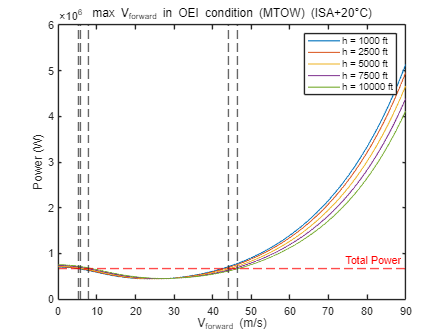

figure
plot(V_forward,P_1_M_20,LineWidth=1)
hold on
plot(V_forward,P_2_M_20,LineWidth=1)
hold on
plot(V_forward,P_3_M_20,LineWidth=1)
hold on
plot(V_forward,P_4_M_20,LineWidth=1)
hold on
plot(V_forward,P_5_M_20,LineWidth=1)
hold on
xline(V_forward(idx_Vmax_1_M),'--')
hold on
xline(V_forward(idx_Vmax_2_M),'--')
hold on
yline(Ptotal_OEI, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_4_M),'--')
hold on
xline(V_forward(idx_Vmax_5_M),'--')
hold on
xline(V_forward(idx_Vmax_3_M),'--')
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('max V_f_o_r_w_a_r_d in OEI condition (MTOW) (ISA+20°C)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

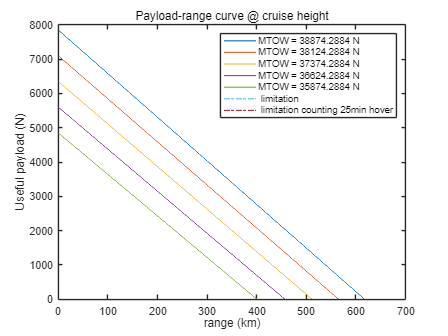

%%%%%% Range—Payload and Endurance—Payload Relations
%%% spesic def
GTOW_diff = 750; % N
hover_time = 25; % min
Wf_range = 0:1:Wf;
W_1 = MTOW;
W_2 = W_1 - GTOW_diff;
W_3 = W_2 - GTOW_diff;
W_4 = W_3 - GTOW_diff;
W_5 = W_4 - GTOW_diff;
W = [W_1,W_2,W_3,W_4,W_5]; % N

%%% hover fuel consumption
P_hover_1_M = PowerClac(W_1,h_cruise,T_cruise ,V_forward,input);
P_hover_2_M = PowerClac(W_2,h_cruise,T_cruise ,V_forward,input);
P_hover_3_M = PowerClac(W_3,h_cruise,T_cruise ,V_forward,input);
P_hover_4_M = PowerClac(W_4,h_cruise,T_cruise ,V_forward,input);
P_hover_5_M = PowerClac(W_5,h_cruise,T_cruise ,V_forward,input);
P_hover_1_M = P_hover_1_M(1);
P_hover_2_M = P_hover_2_M(1);
P_hover_3_M = P_hover_3_M(1);
P_hover_4_M = P_hover_4_M(1);
P_hover_5_M = P_hover_5_M(1);
Wf_hover_1 = SFC * P_hover_1_M * hover_time * 60 * g;
Wf_hover_2 = SFC * P_hover_2_M * hover_time * 60 * g;
Wf_hover_3 = SFC * P_hover_3_M * hover_time * 60 * g;
Wf_hover_4 = SFC * P_hover_4_M * hover_time * 60 * g;
Wf_hover_5 = SFC * P_hover_5_M * hover_time * 60 * g;
W_hover = [Wf_hover_1,Wf_hover_2,Wf_hover_3,Wf_hover_4,Wf_hover_5]; % N

%%% payload range def
Wpay_1 = Wpay - Wf_range;
Wpay_2 = Wpay_1 - GTOW_diff;
Wpay_3 = Wpay_2 - GTOW_diff;
Wpay_4 = Wpay_3 - GTOW_diff;
Wpay_5 = Wpay_4 - GTOW_diff;

%%% range%endur factor calc
R_factor = zeros(size(W));
E_factor = zeros(size(W));
E_factor_c = zeros(size(W));
R_factor_c = zeros(size(W));
for j = 1:length(W)
    PPP_range = PowerClac(W(j),h_cruise,T_cruise ,V_forward,input);
    P_range = PPP_range(5,:);

    k_range = P_range ./ V_forward;
    [~, idx_range] = min(k_range);
    Vrange = V_forward(idx_range);
    R_factor(j) = Vrange / (P_range(idx_range) * SFC);
    [~, idx_endurance] = min(P_range);
    E_factor(j) = 1 / (P_range(idx_endurance) * SFC);
    
    [~,cruise_idx] = min(abs(V_forward - V_cruise));
    E_factor_c(j) = 1 / (P_range(cruise_idx) * SFC);
    R_factor_c(j) = V_cruise / (P_range(cruise_idx) * SFC);
end

%%% range%endur calc
R1 = Wf_range * R_factor(1) *0.001 ./g;
R2 = Wf_range * R_factor(2) *0.001 ./g;
R3 = Wf_range * R_factor(3) *0.001 ./g;
R4 = Wf_range * R_factor(4) *0.001 ./g;
R5 = Wf_range * R_factor(5) *0.001 ./g;
R1_c = Wf_range * R_factor_c(1) *0.001 ./g;
R2_c = Wf_range * R_factor_c(2) *0.001 ./g;
R3_c = Wf_range * R_factor_c(3) *0.001 ./g;
R4_c = Wf_range * R_factor_c(4) *0.001 ./g;
R5_c = Wf_range * R_factor_c(5) *0.001 ./g;
E1 = Wf_range * E_factor(1) ./(g*3600);
E2 = Wf_range * E_factor(2) ./(g*3600);
E3 = Wf_range * E_factor(3) ./(g*3600);
E4 = Wf_range * E_factor(4) ./(g*3600);
E5 = Wf_range * E_factor(5) ./(g*3600);
E1_c = Wf_range * E_factor_c(1) ./(g*3600);
E2_c = Wf_range * E_factor_c(2) ./(g*3600);
E3_c = Wf_range * E_factor_c(3) ./(g*3600);
E4_c = Wf_range * E_factor_c(4) ./(g*3600);
E5_c = Wf_range * E_factor_c(5) ./(g*3600);

%%% limitation calc
maxrange = [max(R1),max(R2),max(R3),max(R4),max(R5)];
maxendurance = [max(E1),max(E2),max(E3),max(E4),max(E5)];
minpay = [min(Wpay_1),min(Wpay_2),min(Wpay_3),min(Wpay_4),min(Wpay_5)];

maxrange_fit = max(R1):0.1:max(R1)+50;
minpay_fit_R = spline(maxrange,minpay,maxrange_fit);
maxendurance_fit = max(E1):0.01:max(E1)+0.5;

minpay_fit_E = spline(maxendurance,minpay,maxendurance_fit);
minpay_hover = minpay + W_hover;
[~,idx_range_hover_1] = min(abs(Wpay_1 - minpay_hover(1)));
[~,idx_range_hover_2] = min(abs(Wpay_2 - minpay_hover(2)));
[~,idx_range_hover_3] = min(abs(Wpay_3 - minpay_hover(3)));
[~,idx_range_hover_4] = min(abs(Wpay_4 - minpay_hover(4)));
[~,idx_range_hover_5] = min(abs(Wpay_5 - minpay_hover(5)));
maxrange_hover = zeros(1,5);
maxendurance_hover = zeros(1,5);
maxrange_hover(1) =  R1(idx_range_hover_1);
maxrange_hover(2) =  R2(idx_range_hover_2);
maxrange_hover(3) =  R3(idx_range_hover_3);
maxrange_hover(4) =  R4(idx_range_hover_4);
maxrange_hover(5) =  R5(idx_range_hover_5);
maxendurance_hover(1) = E1(idx_range_hover_1);
maxendurance_hover(2) = E2(idx_range_hover_2);
maxendurance_hover(3) = E3(idx_range_hover_3);
maxendurance_hover(4) = E4(idx_range_hover_4);
maxendurance_hover(5) = E5(idx_range_hover_5);
maxrange_fit_hover = maxrange_hover(1):0.1:maxrange_hover(1)+50;
minpay_fit_R_hover = spline(maxrange_hover,minpay_hover,maxrange_fit_hover);
maxendurance_fit_hover = maxendurance_hover(1):0.01:maxendurance_hover(1)+0.5;
minpay_fit_E_hover = spline(maxendurance_hover,minpay_hover,maxendurance_fit_hover);
maxrange_c = [max(R1_c),max(R2_c),max(R3_c),max(R4_c),max(R5_c)];
maxendurance_c = [max(E1_c),max(E2_c),max(E3_c),max(E4_c),max(E5_c)];
minpay_c = [min(Wpay_1),min(Wpay_2),min(Wpay_3),min(Wpay_4),min(Wpay_5)];

maxrange_fit_c = max(R1_c):0.1:max(R1_c)+20;
minpay_fit_R_c = spline(maxrange_c,minpay_c,maxrange_fit_c);
maxendurance_fit_c = max(E1_c):0.01:max(E1_c)+0.2;

minpay_fit_E_c = spline(maxendurance_c,minpay_c,maxendurance_fit_c);
minpay_hover = minpay_c + W_hover;
maxrange_hover_c = zeros(1,5);
maxendurance_hover_c = zeros(1,5);
maxrange_hover_c(1) =  R1_c(idx_range_hover_1);
maxrange_hover_c(2) =  R2_c(idx_range_hover_2);
maxrange_hover_c(3) =  R3_c(idx_range_hover_3);
maxrange_hover_c(4) =  R4_c(idx_range_hover_4);
maxrange_hover_c(5) =  R5_c(idx_range_hover_5);
maxendurance_hover_c(1) = E1_c(idx_range_hover_1);
maxendurance_hover_c(2) = E2_c(idx_range_hover_2);
maxendurance_hover_c(3) = E3_c(idx_range_hover_3);
maxendurance_hover_c(4) = E4_c(idx_range_hover_4);
maxendurance_hover_c(5) = E5_c(idx_range_hover_5);
maxrange_fit_hover_c = maxrange_hover_c(1):0.1:maxrange_hover_c(1)+20;
minpay_fit_R_hover_c = spline(maxrange_hover_c,minpay_hover,maxrange_fit_hover_c);
maxendurance_fit_hover_c = maxendurance_hover_c(1):0.01:maxendurance_hover_c(1)+0.1;
minpay_fit_E_hover_c = spline(maxendurance_hover_c,minpay_hover,maxendurance_fit_hover_c);

%%% plots
figure
plot(R1,Wpay_1,LineWidth=1)
hold on
plot(R2,Wpay_2,LineWidth=1)
hold on
plot(R3,Wpay_3,LineWidth=1)
hold on
plot(R4,Wpay_4,LineWidth=1)
hold on
plot(R5,Wpay_5,LineWidth=1)
hold on
plot(maxrange_fit, minpay_fit_R, '-.', 'LineWidth', 1, 'DisplayName', 'limitation');
hold on
plot(maxrange_fit_hover, minpay_fit_R_hover, '-.', 'LineWidth', 1, 'DisplayName', 'limitation');
legend(['MTOW = ',num2str(W_1),' N'],['MTOW = ',num2str(W_2),' N'],['MTOW = ',num2str(W_3),' N'],['MTOW = ',num2str(W_4),' N'],['MTOW = ',num2str(W_5),' N'],' limitation',' limitation counting 25min hover')
title('Payload-range curve @ cruise height')
xlabel('range (km)')
ylabel('Useful payload (N)')
ylim([0 8000])
hold off

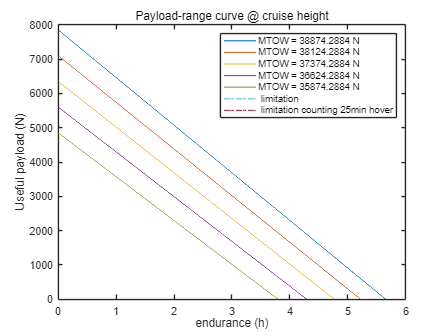

figure
plot(E1,Wpay_1,LineWidth=1)
hold on
plot(E2,Wpay_2,LineWidth=1)
hold on
plot(E3,Wpay_3,LineWidth=1)
hold on
plot(E4,Wpay_4,LineWidth=1)
hold on
plot(E5,Wpay_5,LineWidth=1)
hold on
plot(maxendurance_fit,minpay_fit_E, '-.', 'LineWidth', 1, 'DisplayName', 'limitation')
hold on
plot(maxendurance_fit_hover,minpay_fit_E_hover, '-.', 'LineWidth', 1, 'DisplayName', 'limitation')
legend(['MTOW = ',num2str(W_1),' N'],['MTOW = ',num2str(W_2),' N'],['MTOW = ',num2str(W_3),' N'],['MTOW = ',num2str(W_4),' N'],['MTOW = ',num2str(W_5),' N'],' limitation',' limitation counting 25min hover')
title('Payload-range curve @ cruise height')
xlabel('endurance (h)')
ylabel('Useful payload (N)')
ylim([0 8000])
hold off

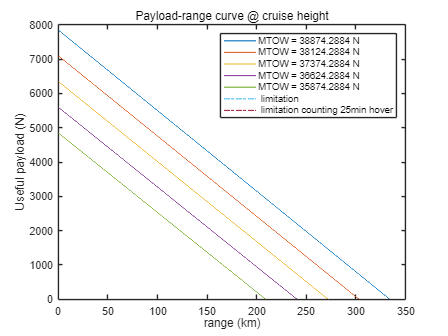

figure
plot(R1_c,Wpay_1,LineWidth=1)
hold on
plot(R2_c,Wpay_2,LineWidth=1)
hold on
plot(R3_c,Wpay_3,LineWidth=1)
hold on
plot(R4_c,Wpay_4,LineWidth=1)
hold on
plot(R5_c,Wpay_5,LineWidth=1)
hold on
plot(maxrange_fit_c, minpay_fit_R_c, '-.', 'LineWidth', 1, 'DisplayName', 'limitation');
hold on
plot(maxrange_fit_hover_c, minpay_fit_R_hover_c, '-.', 'LineWidth', 1, 'DisplayName', 'limitation');
legend(['MTOW = ',num2str(W_1),' N'],['MTOW = ',num2str(W_2),' N'],['MTOW = ',num2str(W_3),' N'],['MTOW = ',num2str(W_4),' N'],['MTOW = ',num2str(W_5),' N'],' limitation',' limitation counting 25min hover')
title('Payload-range curve @ cruise height')
xlabel('range (km)')
ylabel('Useful payload (N)')
ylim([0 8000])
hold off

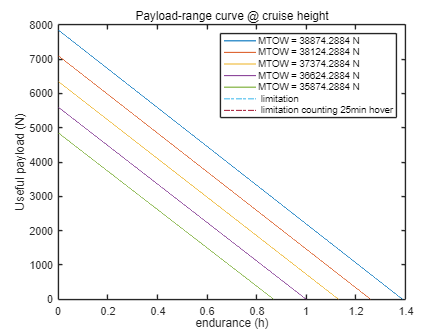

figure
plot(E1_c,Wpay_1,LineWidth=1)
hold on
plot(E2_c,Wpay_2,LineWidth=1)
hold on
plot(E3_c,Wpay_3,LineWidth=1)
hold on
plot(E4_c,Wpay_4,LineWidth=1)
hold on
plot(E5_c,Wpay_5,LineWidth=1)
hold on
plot(maxendurance_fit_c,minpay_fit_E_c, '-.', 'LineWidth', 1, 'DisplayName', 'limitation')
hold on
plot(maxendurance_fit_hover_c,minpay_fit_E_hover_c, '-.', 'LineWidth', 1, 'DisplayName', 'limitation')
legend(['MTOW = ',num2str(W_1),' N'],['MTOW = ',num2str(W_2),' N'],['MTOW = ',num2str(W_3),' N'],['MTOW = ',num2str(W_4),' N'],['MTOW = ',num2str(W_5),' N'],' limitation',' limitation counting 25min hover')
title('Payload-range curve @ cruise height')
xlabel('endurance (h)')
ylabel('Useful payload (N)')
ylim([0 8000])
hold off

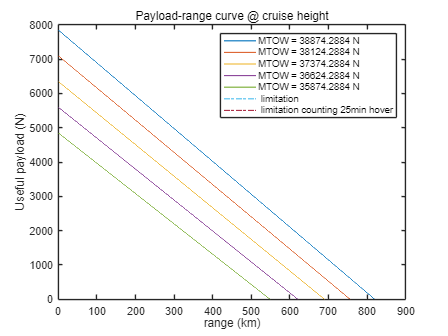

%%%%%% L/D Method
L_D = 3.85;

%%% range&endur clac
E_factor_LD = zeros(size(W));
R_factor_LD = zeros(size(W));
for j = 1:length(W)
    P_L_D = W(j) * V_cruise / L_D;
    P_L_D = (P_L_D + Paux_total) * kappa_trans;
    E_factor_LD(j) = 1 / (P_L_D * SFC);
    R_factor_LD(j) = V_cruise / (P_L_D * SFC);
end
R1_LD = Wf_range * R_factor_LD(1) *0.001 ./g;
R2_LD = Wf_range * R_factor_LD(2) *0.001 ./g;
R3_LD = Wf_range * R_factor_LD(3) *0.001 ./g;
R4_LD = Wf_range * R_factor_LD(4) *0.001 ./g;
R5_LD = Wf_range * R_factor_LD(5) *0.001 ./g;
E1_LD = Wf_range * E_factor_LD(1) ./(g*3600);
E2_LD = Wf_range * E_factor_LD(2) ./(g*3600);
E3_LD = Wf_range * E_factor_LD(3) ./(g*3600);
E4_LD = Wf_range * E_factor_LD(4) ./(g*3600);
E5_LD = Wf_range * E_factor_LD(5) ./(g*3600);

%%% limitation calc
maxrange_LD = [max(R1_LD),max(R2_LD),max(R3_LD),max(R4_LD),max(R5_LD)];
maxendurance_LD = [max(E1_LD),max(E2_LD),max(E3_LD),max(E4_LD),max(E5_LD)];
minpay_LD = [min(Wpay_1),min(Wpay_2),min(Wpay_3),min(Wpay_4),min(Wpay_5)];

maxrange_fit_LD = max(R1_LD):0.1:max(R1_LD)+50;
minpay_fit_R_LD = spline(maxrange_LD,minpay_LD,maxrange_fit_LD);
maxendurance_fit_LD = max(E1_LD):0.01:max(E1_LD)+0.2;

minpay_fit_E_LD = spline(maxendurance_LD,minpay_LD,maxendurance_fit_LD);
minpay_hover = minpay_LD + W_hover;
maxrange_hover_LD = zeros(1,5);
maxendurance_hover_LD = zeros(1,5);
maxrange_hover_LD(1) =  R1_LD(idx_range_hover_1);
maxrange_hover_LD(2) =  R2_LD(idx_range_hover_2);
maxrange_hover_LD(3) =  R3_LD(idx_range_hover_3);
maxrange_hover_LD(4) =  R4_LD(idx_range_hover_4);
maxrange_hover_LD(5) =  R5_LD(idx_range_hover_5);
maxendurance_hover_LD(1) = E1_LD(idx_range_hover_1);
maxendurance_hover_LD(2) = E2_LD(idx_range_hover_2);
maxendurance_hover_LD(3) = E3_LD(idx_range_hover_3);
maxendurance_hover_LD(4) = E4_LD(idx_range_hover_4);
maxendurance_hover_LD(5) = E5_LD(idx_range_hover_5);

maxrange_fit_hover_LD = maxrange_hover_LD(1):0.1:maxrange_hover_LD(1)+50;
minpay_fit_R_hover_LD = spline(maxrange_hover_LD,minpay_hover,maxrange_fit_hover_LD);
maxendurance_fit_hover_LD = maxendurance_hover_LD(1):0.01:maxendurance_hover_LD(1)+0.2;

minpay_fit_E_hover_LD = spline(maxendurance_hover_LD,minpay_hover,maxendurance_fit_hover_LD);

%%% plots
figure
plot(R1_LD,Wpay_1,LineWidth=1)
hold on
plot(R2_LD,Wpay_2,LineWidth=1)
hold on
plot(R3_LD,Wpay_3,LineWidth=1)
hold on
plot(R4_LD,Wpay_4,LineWidth=1)
hold on
plot(R5_LD,Wpay_5,LineWidth=1)
hold on
plot(maxrange_fit_LD, minpay_fit_R_LD, '-.', 'LineWidth', 1, 'DisplayName', 'limitation');
hold on
plot(maxrange_fit_hover_LD, minpay_fit_R_hover_LD, '-.', 'LineWidth', 1, 'DisplayName', 'limitation');
legend(['MTOW = ',num2str(W_1),' N'],['MTOW = ',num2str(W_2),' N'],['MTOW = ',num2str(W_3),' N'],['MTOW = ',num2str(W_4),' N'],['MTOW = ',num2str(W_5),' N'],' limitation',' limitation counting 25min hover')
title('Payload-range curve @ cruise height')
xlabel('range (km)')
ylabel('Useful payload (N)')
ylim([0 8000])
hold off

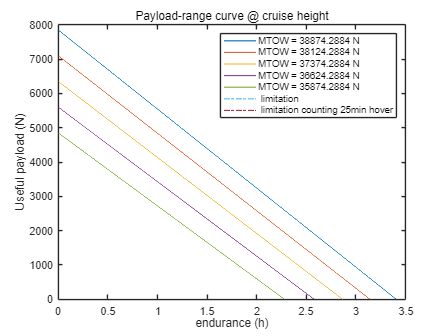

figure
plot(E1_LD,Wpay_1,LineWidth=1)
hold on
plot(E2_LD,Wpay_2,LineWidth=1)
hold on
plot(E3_LD,Wpay_3,LineWidth=1)
hold on
plot(E4_LD,Wpay_4,LineWidth=1)
hold on
plot(E5_LD,Wpay_5,LineWidth=1)
hold on
plot(maxendurance_fit_LD,minpay_fit_E_LD, '-.', 'LineWidth', 1, 'DisplayName', 'limitation')
hold on
plot(maxendurance_fit_hover_LD,minpay_fit_E_hover_LD, '-.', 'LineWidth', 1, 'DisplayName', 'limitation')
legend(['MTOW = ',num2str(W_1),' N'],['MTOW = ',num2str(W_2),' N'],['MTOW = ',num2str(W_3),' N'],['MTOW = ',num2str(W_4),' N'],['MTOW = ',num2str(W_5),' N'],' limitation',' limitation counting 25min hover')
title('Payload-range curve @ cruise height')
xlabel('endurance (h)')
ylabel('Useful payload (N)')
ylim([0 8000])
hold off

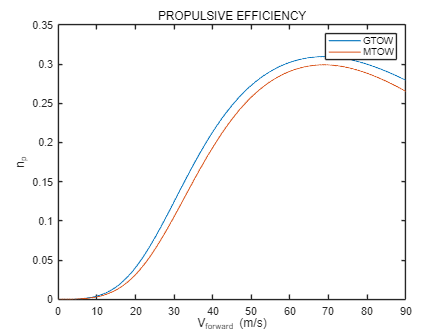

%%%%%% PROPULSIVE EFFICIENCY
np_G = GTOW .* V_forward .* tan(alp_G(3,:)) ./ P_3_G;
np_M = MTOW .* V_forward .* tan(alp_M(3,:)) ./ P_3_M;
figure
plot(V_forward,np_G,LineWidth=1)
hold on
plot(V_forward,np_M,LineWidth=1)
legend('GTOW','MTOW')
title('PROPULSIVE EFFICIENCY')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('n_p')
hold off

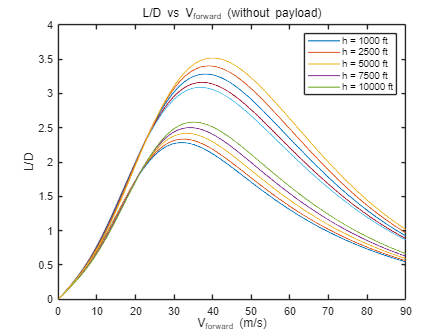

%%%%%% L/D
%%% L/D clac
L_D_1_G = (V_tip * GTOW) .* mu ./ (P_1_G);
L_D_2_G = (V_tip * GTOW) .* mu ./ (P_2_G);
L_D_3_G = (V_tip * GTOW) .* mu ./ (P_3_G);
L_D_4_G = (V_tip * GTOW) .* mu ./ (P_4_G);
L_D_5_G = (V_tip * GTOW) .* mu ./ (P_5_G);
L_D_1_M = (V_tip * MTOW) .* mu ./ (P_1_M);
L_D_2_M = (V_tip * MTOW) .* mu ./ (P_2_M);
L_D_3_M = (V_tip * MTOW) .* mu ./ (P_3_M);
L_D_4_M = (V_tip * MTOW) .* mu ./ (P_4_M);
L_D_5_M = (V_tip * MTOW) .* mu ./ (P_5_M);
L_D_1_G_r = (V_tip * GTOW) .* mu ./ (PPP_1_G(1,:)+PPP_1_G(2,:));
L_D_2_G_r = (V_tip * GTOW) .* mu ./ (PPP_2_G(1,:)+PPP_2_G(2,:));
L_D_3_G_r = (V_tip * GTOW) .* mu ./ (PPP_3_G(1,:)+PPP_3_G(2,:));
L_D_4_G_r = (V_tip * GTOW) .* mu ./ (PPP_4_G(1,:)+PPP_4_G(2,:));
L_D_5_G_r = (V_tip * GTOW) .* mu ./ (PPP_5_G(1,:)+PPP_5_G(2,:));
L_D_1_M_r = (V_tip * MTOW) .* mu ./ (PPP_1_M(1,:)+PPP_1_M(2,:));
L_D_2_M_r = (V_tip * MTOW) .* mu ./ (PPP_2_M(1,:)+PPP_2_M(2,:));
L_D_3_M_r = (V_tip * MTOW) .* mu ./ (PPP_3_M(1,:)+PPP_3_M(2,:));
L_D_4_M_r = (V_tip * MTOW) .* mu ./ (PPP_4_M(1,:)+PPP_4_M(2,:));
L_D_5_M_r = (V_tip * MTOW) .* mu ./ (PPP_5_M(1,:)+PPP_5_M(2,:));


%%% plots
figure
plot(V_forward,L_D_1_G,LineWidth=1)
hold on
plot(V_forward,L_D_2_G,LineWidth=1)
hold on
plot(V_forward,L_D_3_G,LineWidth=1)
hold on
plot(V_forward,L_D_4_G,LineWidth=1)
hold on
plot(V_forward,L_D_5_G,LineWidth=1)
hold on
plot(V_forward,L_D_1_G_r,LineWidth=1)
hold on
plot(V_forward,L_D_2_G_r,LineWidth=1)
hold on
plot(V_forward,L_D_3_G_r,LineWidth=1)
hold on
plot(V_forward,L_D_4_G_r,LineWidth=1)
hold on
plot(V_forward,L_D_5_G_r,LineWidth=1)
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('L/D vs V_f_o_r_w_a_r_d (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('L/D')
hold off

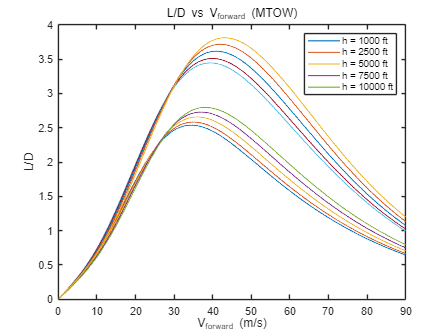

figure
plot(V_forward,L_D_1_M,LineWidth=1)
hold on
plot(V_forward,L_D_2_M,LineWidth=1)
hold on
plot(V_forward,L_D_3_M,LineWidth=1)
hold on
plot(V_forward,L_D_4_M,LineWidth=1)
hold on
plot(V_forward,L_D_5_M,LineWidth=1)
hold on
plot(V_forward,L_D_1_M_r,LineWidth=1)
hold on
plot(V_forward,L_D_2_M_r,LineWidth=1)
hold on
plot(V_forward,L_D_3_M_r,LineWidth=1)
hold on
plot(V_forward,L_D_4_M_r,LineWidth=1)
hold on
plot(V_forward,L_D_5_M_r,LineWidth=1)
legend(['h = ',num2str(hh(1)),' ft'],['h = ',num2str(hh(2)),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(hh(4)),' ft'],['h = ',num2str(hh(5)),' ft'])
title('L/D vs V_f_o_r_w_a_r_d (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('L/D')
hold off

% %%%%%% H-V diagram
% for i = 0:10:15000


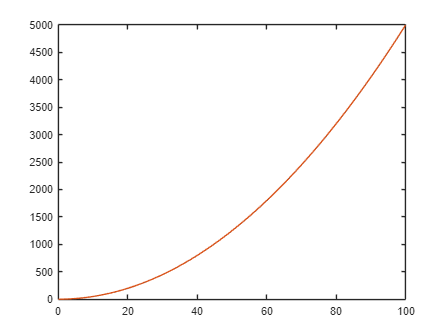

%%%%%% Autorotation (rate of  decent) (in hovering)
%%% descent distance vs time
I_R = 500;
tau_G = I_R * omega / P_3_G(1);
tau_M = I_R * omega / P_3_M(1);
t = 0:0.0001:100;
h_descent_G = 0.5 .* t.^2 - tau_G .* t + tau_G^2 .* log((t + tau_G) ./ tau_G);
h_descent_M = 0.5 .* t.^2 - tau_M .* t + tau_M^2 .* log((t + tau_M) ./ tau_M);

%%% distance==h_cruise-----max time
[~,descent_idx_G] = min(abs(h_descent_G - h_cruise));
[~,descent_idx_M] = min(abs(h_descent_M - h_cruise));
t_max_G = t(descent_idx_G);
t_max_M = t(descent_idx_M);
figure
plot(t,h_descent_G)
hold on
plot(t,h_descent_M)
hold on
yline(h_cruise)
hold off

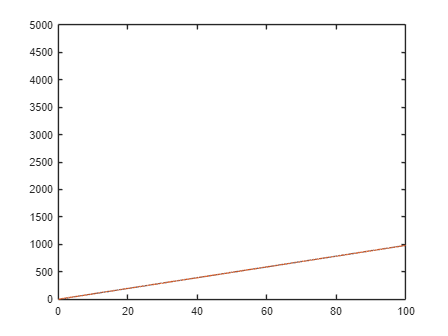

%%% Vd_hover vs t
t_hover_G = 0:0.01:t_max_G;
t_hover_M = 0:0.01:t_max_M;
Vd_hover_G = g .* t_hover_G .* (t_hover_G ./ (t_hover_G + tau_G));
Vd_hover_M = g .* t_hover_M .* (t_hover_M ./ (t_hover_M + tau_M));
figure
plot(t_hover_G,Vd_hover_G)
hold on
plot(t_hover_M,Vd_hover_M)
hold on
yline(h_cruise)
hold off

%%%%%% Autorotation (rate of  decent) (in forward flight)
%%% Vd calc
rho_a = rho_0*(1-6.876*10^-6*h_cruise)^4.265;
kappa_i = kappa_ii .* cosh(7.5 .* mu.^2);
CW_G = GTOW / (0.5*rho_a*A*omega^2*R^2);
CW_M = MTOW / (0.5*rho_a*A*omega^2*R^2);
AAAG = PowerClac(GTOW,h_cruise,T_cruise ,V_forward,input);
AAAM = PowerClac(MTOW,h_cruise,T_cruise ,V_forward,input);
V_d_G = 60*omega*R*(- kappa_int * 2 * kappa_i * CW_G ./ (2*sqrt(mu.^2 + AAAG(6,:).^2)) - (solidity * Cd0 * 2 / (8*CW_M)) .* (1 + kappa_02.*mu.^2 + kappa_04.*mu.^4) - (0.5 * f / A) .* mu.^3 ./ CW_G);
V_d_M = 60*omega*R*(- kappa_int * 2 * kappa_i * CW_M ./ (2*sqrt(mu.^2 + AAAM(6,:).^2)) - (solidity * Cd0 * 2 / (8*CW_M)) .* (1 + kappa_02.*mu.^2 + kappa_04.*mu.^4) - (0.5 * f / A) .* mu.^3 ./ CW_M);

%%% Vmd clac
[V_md_G,idx_V_md_G] = min(abs(V_d_G));
[V_md_M,idx_V_md_M] = min(abs(V_d_M));
disp(['GTOW min rate of decent is ',num2str(V_md_G)])

GTOW min rate of decent is 1460.8478


disp(['corresponding forward speed is ',num2str(V_forward(idx_V_md_G))])

corresponding forward speed is 52.1


disp(['MTOW min rate of decent is ',num2str(V_md_M)])

MTOW min rate of decent is 1682.7833


disp(['corresponding forward speed is ',num2str(V_forward(idx_V_md_M))])

corresponding forward speed is 56.2


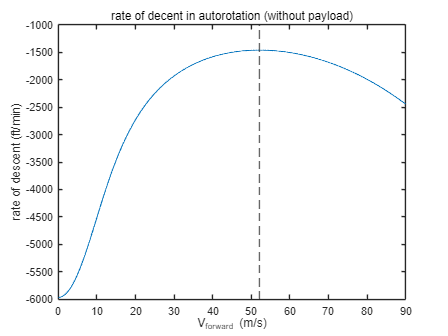

%%% plots
figure
plot(V_forward,V_d_G,"LineWidth",1)
hold on
xline(V_forward(idx_V_md_G),'--')
title('rate of decent in autorotation (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of descent (ft/min)')
hold off

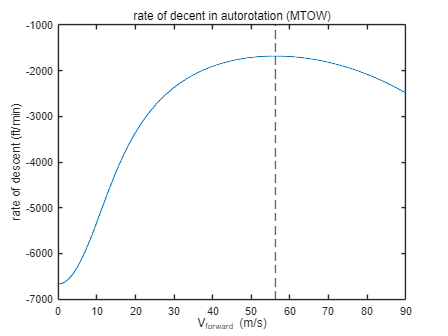

figure
plot(V_forward,V_d_M,"LineWidth",1)
hold on
xline(V_forward(idx_V_md_M),'--')
title('rate of decent in autorotation (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of descent (ft/min)')
hold off

%%%%%% Ground effect (in hovering)
z_R = 0:0.001:3;
CT = MTOW/(rho_0*A*omega^2*R^2);
vh = sqrt(MTOW / (2*rho_0*A));
lambdai = sqrt(CT/2); % λ₀ (hover value)
Nmax = 4000;
tol = 5e-4;
V_forward_kg = 0:0.01:2*vh;
mu_kg = V_forward_kg ./ V_tip;
alp_msl_M_kg = atan(((0.5*rho_0*f).* V_forward_kg.^2) ./ MTOW);
for n = 1:Nmax
    lambda_new = mu_kg .* tan(alp_msl_M_kg) + CT ./ ( 2 .* sqrt( mu_kg.^2 + lambdai.^2 ) );
if all( abs(lambda_new - lambdai) ./ lambda_new < tol )
lambdai = lambda_new; % converged – keep the final value
break
end
end
disp(lambdai)

    0.0609



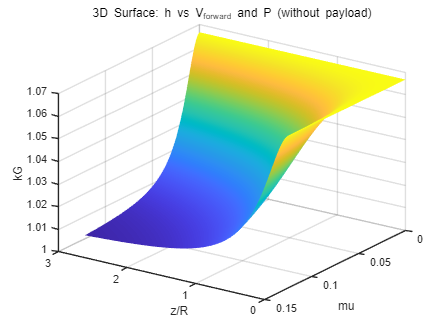

kG = zeros(length(z_R),length(V_forward_kg));
for i = 1:length(z_R)
    kG(i,:) = 1 ./ (1 - 0.25^2 ./ (1 + (mu_kg ./ lambdai).^2 .* z_R(i)^2));
end
[muu, z_RR] = meshgrid(mu_kg, z_R);
figure
s = surf(z_RR, muu, kG);
xlabel('z/R');
ylabel('mu');
zlabel('kG');
title('3D Surface: h vs V_f_o_r_w_a_r_d and P (without payload)');
grid on
shading interp
hold off

view([-145.5000 27.7500])

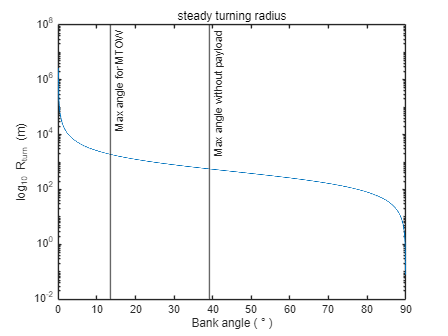

%%%%%% Maneuvers (steady)
%%% radius calc
bank_angle = 0:0.01:90;
R_turn = V_cruise^2 ./ (g .* sqrt(1 ./ cosd(bank_angle).^2 - 1));

%%% max bank angle calc
bank_angle_max_G = acos(GTOW/T_max);
bank_angle_max_M = acos(MTOW/T_max);
bank_angle_max_G = bank_angle_max_G * 180 / pi;
bank_angle_max_M = bank_angle_max_M * 180 / pi;

figure
plot(bank_angle,R_turn,"LineWidth",1)
set(gca, 'YScale', 'log')
hold on
xline(bank_angle_max_G,'label','Max angle without payload')
hold on
xline(bank_angle_max_M,'label','Max angle for MTOW')
title('steady turning radius')
xlabel('Bank angle ( ° )')
ylabel('log_1_0 R_t_u_r_n (m)')
xlim([0 90])

%%%%%% Maneuvers (transit)





%%%%%% VRS effect




